% Definer funksjonen vi ønsker å integrere
f = @(x) x.^2; % Endre denne til hvilken som helst annen funksjon

% Definer integrasjonsintervallet [a, b]
a = 0; % Nedre grense
b = 1; % Øvre grense

% Antall trapeser (jo flere, desto bedre tilnærming)
N = 50;

% Beregn bredden av hvert trapes
h = (b - a) / N;

% Beregn x-verdiene der vi evaluerer funksjonen
x = a:h:b;

% Evaluer funksjonen ved disse x-verdiene
y = f(x);

% Implementer trapesmetoden
I = (h/2) * (y(1) + 2*sum(y(2:end-1)) + y(end));


% Vis resultatet av integrasjonen
fprintf('Tilnærmet verdi av integralet ved trapesmetoden: %f\n', I);

Tilnærmet verdi av integralet ved trapesmetoden: 0.333400


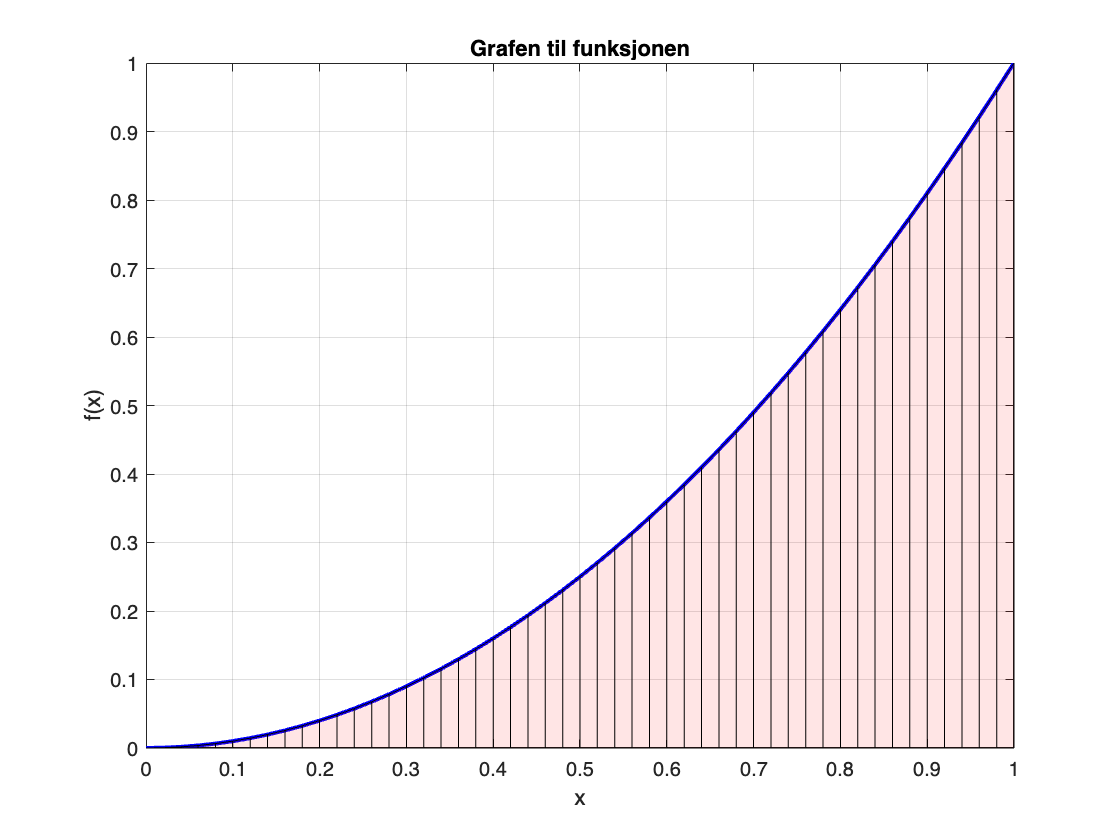


% Plot funksjonen
figure;
plot(x, y, 'b-', 'LineWidth', 2);
title('Grafen til funksjonen');
xlabel('x');
ylabel('f(x)');
grid on;

% Highlight trapesene under kurven
hold on;
for i = 1:(length(x) - 1)
    xx = [x(i), x(i), x(i+1), x(i+1)];
    yy = [0, f(x(i)), f(x(i+1)), 0];
    fill(xx, yy, 'r', 'FaceAlpha', 0.1);
end
hold off;